# Dataset Straight 1 Curve Analysis

#### Load Dataset

clear all;
datasetPath = 'keliling_ITS.csv';
dataset = readtable(datasetPath);
% load("reference_lurus_blokT_asrama.mat","referencePoints")

#### Method Tested:

- Sensor Position are Corrected using Lever Effect.

- Time differences are synchronized.

- four IMU measurement are fused into VIMU.

#### Fault Condition: 

- NO FAULT

#### Normalize axis & Bias Correction

dataset = norm4imu(dataset);
dataset = correction4imu("calibrate_value.mat", dataset);

#### GNSS position transformation

coor_ecef = [dataset.gps__ecefx, dataset.gps__ecefy, dataset.gps__ecefz];
coor_lla = ecef2lla(coor_ecef, 'WGS84');
[cn, ce, cd] = ecef2ned(coor_ecef(:,1), coor_ecef(:,2), coor_ecef(:,3), coor_lla(1,1), coor_lla(1,2), coor_lla(1,3), wgs84Ellipsoid('meter'));
coor_ned = [cn, ce, cd]

coor_ned =     0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000


#### GNSS Position Sample Plot

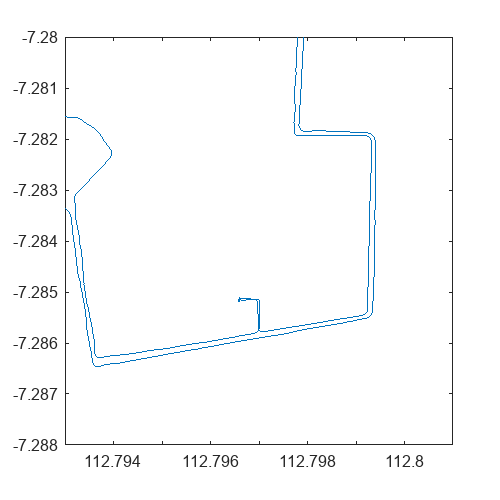

fig = figure;
set(fig, 'Position', [100, 100, 400, 400]);
plot(coor_lla(:,2), coor_lla(:,1));
axis([112.793 112.801 -7.288 -7.280 ]);

#### Accel + Gyro Sample Plot

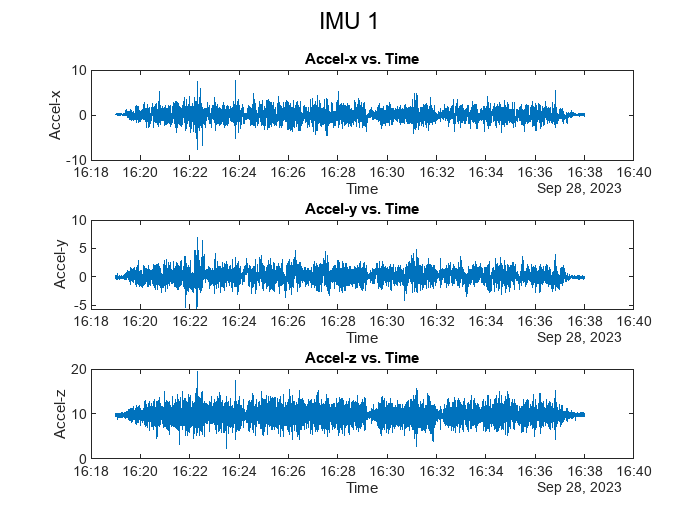

tbl2subplot(dataset, {'i2c__cimu1__accel__x', 'i2c__cimu1__accel__y', 'i2c__cimu1__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 1');

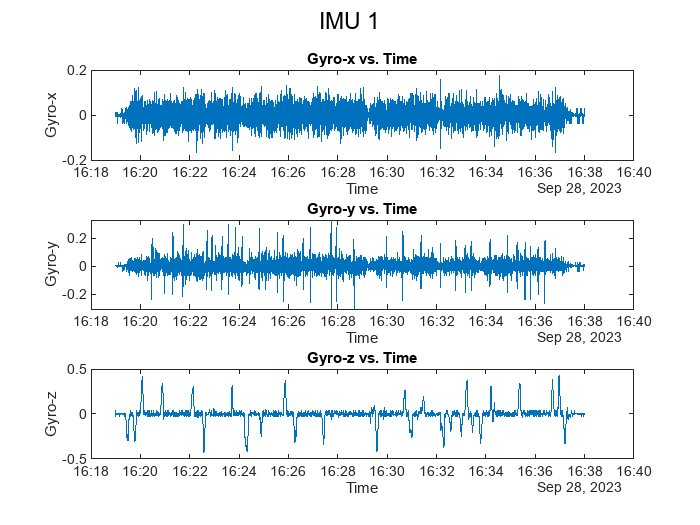

tbl2subplot(dataset, {'i2c__cimu1__gyro__x', 'i2c__cimu1__gyro__y', 'i2c__cimu1__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 1');

#### Lever Correction


$$\Delta v=\Delta\breve{\textbf{v}}+ \textbf{A} \cdot \textbf{r}_\text{IMU}^B$$



$$\textbf{A} = \left[\begin{array}{ccc}
        \left(\omega_y^2+\omega_z^2\right) & -\left(\omega_x \omega_y-\dot{\omega}_z\right) & -\left(\omega_x \omega_z+\dot{\omega}_y\right) \\
        -\left(\omega_x \omega_y+\dot{\omega}_z\right) & \left(\omega_x^2+\omega_z^2\right) & -\left(\omega_y \omega_z-\dot{\omega}_x\right) \\
        -\left(\omega_x \omega_z-\dot{\omega}_y\right) & -\left(\omega_y \omega_z+\dot{\omega}_x\right) & \left(\omega_x^2+\omega_y^2\right)
        \end{array}\right]$$


ca = zeros(size(coor_lla,1),3,4);
ca(:,1,1) = dataset.i2c__cimu1__accel__x; ca(:,2,1) = dataset.i2c__cimu1__accel__y; ca(:,3,1) = dataset.i2c__cimu1__accel__z;
ca(:,1,2) = dataset.i2c__cimu2__accel__x; ca(:,2,2) = dataset.i2c__cimu2__accel__y; ca(:,3,2) = dataset.i2c__cimu2__accel__z;
ca(:,1,3) = dataset.i2c__cimu3__accel__x; ca(:,2,3) = dataset.i2c__cimu3__accel__y; ca(:,3,3) = dataset.i2c__cimu3__accel__z;
ca(:,1,4) = dataset.i2c__cimu4__accel__x; ca(:,2,4) = dataset.i2c__cimu4__accel__y; ca(:,3,4) = dataset.i2c__cimu4__accel__z;

cw = zeros(size(coor_lla,1),3,4);
cw(:,1,1) = dataset.i2c__cimu1__gyro__x; cw(:,2,1) = dataset.i2c__cimu1__gyro__y; cw(:,3,1) = dataset.i2c__cimu1__gyro__z;
cw(:,1,2) = dataset.i2c__cimu2__gyro__x; cw(:,2,2) = dataset.i2c__cimu2__gyro__y; cw(:,3,2) = dataset.i2c__cimu2__gyro__z;
cw(:,1,3) = dataset.i2c__cimu3__gyro__x; cw(:,2,3) = dataset.i2c__cimu3__gyro__y; cw(:,3,3) = dataset.i2c__cimu3__gyro__z;
cw(:,1,4) = dataset.i2c__cimu4__gyro__x; cw(:,2,4) = dataset.i2c__cimu4__gyro__y; cw(:,3,4) = dataset.i2c__cimu4__gyro__z;

cdw = zeros(size(coor_lla,1),3,4);
cdw(2:end,1,1) = diff(cw(:,1,1)); cdw(2:end,2,1) = diff(cw(:,2,1)); cdw(2:end,3,1) = diff(cw(:,3,1));
cdw(2:end,1,2) = diff(cw(:,1,2)); cdw(2:end,2,2) = diff(cw(:,2,2)); cdw(2:end,3,2) = diff(cw(:,3,2));
cdw(2:end,1,3) = diff(cw(:,1,3)); cdw(2:end,2,3) = diff(cw(:,2,3)); cdw(2:end,3,3) = diff(cw(:,3,3));
cdw(2:end,1,4) = diff(cw(:,1,4)); cdw(2:end,2,4) = diff(cw(:,2,4)); cdw(2:end,3,4) = diff(cw(:,3,4));

rimu = zeros(4,3);
rimu(1,:) = [1.1; 0; 0.43];
rimu(2,:) = [-0.26; 0.87; 0.1];
rimu(3,:) = [0.26; 0.87; 0.1];
rimu(4,:) = [-1.3; 0; 0.35];

la = zeros(size(coor_lla,1),3,4);
for nImu = 1:4
    parfor nMeasure = 1:size(coor_lla, 1)
        la(nMeasure,:,nImu) = calcLever(reshape(ca(nMeasure,:,nImu), 3, 1), reshape(cw(nMeasure,:,nImu), 3, 1), reshape(cdw(nMeasure,:,nImu), 3, 1), reshape(rimu(nImu,:), 3, 1));
    end
end

dataset.i2c__limu1__accel__x = la(:,1,1); dataset.i2c__limu1__accel__y = la(:,2,1); dataset.i2c__limu1__accel__z = la(:,3,1);
dataset.i2c__limu2__accel__x = la(:,1,2); dataset.i2c__limu2__accel__y = la(:,2,2); dataset.i2c__limu2__accel__z = la(:,3,2);
dataset.i2c__limu3__accel__x = la(:,1,3); dataset.i2c__limu3__accel__y = la(:,2,3); dataset.i2c__limu3__accel__z = la(:,3,3);
dataset.i2c__limu4__accel__x = la(:,1,4); dataset.i2c__limu4__accel__y = la(:,2,4); dataset.i2c__limu4__accel__z = la(:,3,4);

#### IMU Observation Fusion


$$\Delta \textbf{\bar{v} }_f^B=\frac{\sum_{i=1}^{n} w_{g_i}^{-1} \Delta \textbf{v}_{f i}^B}{\sum_{i=1}^{n} w_{g_i}^{-1}}$$



$$\Delta \textbf{\bar{\theta} }_{IB}^B=\frac{\sum_{i=1}^{n} w_{\omega_i}^{-1} \Delta \textbf{\theta}_{IB i}^B}{\sum_{i=1}^{n} w_{\omega_i}^{-1}}$$



$$w_{g_i}=\left|\Delta \textbf{v}_{f_i}^B-\text{median}\left(\Delta \textbf{v}_{f_i}^B\right)\right| \left|\textbf{r}^{B}_{\text{IMU}_i}\right|+ \epsilon$$



$$w_{g_i}=\left|\Delta \textbf{\theta}_{IB_i}^B-\text{median}\left(\Delta \textbf{\theta}_{IB_i}^B\right)\right| \left|\textbf{r}^{B}_{\text{IMU}_i}\right|+ \epsilon$$


epsilon = 1e-6;
vimu_a = zeros(size(coor_lla,1),3);
vimu_w = zeros(size(coor_lla,1),3);
parfor nMeasure = 1:size(coor_lla,1)
    vf = reshape(la(nMeasure,:,:), 3, 4)';
    tb = reshape(cw(nMeasure,:,:), 3, 4)';

    vf1 = vf(:,1); vf2 = vf(:,2); vf3 = vf(:,3);
    tb1 = tb(:,1); tb2 = tb(:,2); tb3 = tb(:,3);

    w_g = 1./(abs(vf - [median(vf1(vf1~=0)) median(vf2(vf2~=0)) median(vf3(vf3~=0))]).*vecnorm(rimu, 2, 2) + epsilon);
    w_omega = 1./(abs(tb - [median(tb1(tb1~=0)) median(tb2(tb2~=0)) median(tb3(tb3~=0))]).*vecnorm(rimu, 2, 2) + epsilon);

    sum_vwg = sum(vf .* w_g);
    sum_wg = sum(w_g);
    vimu_a(nMeasure,:) = sum_vwg ./ sum_wg;

    sum_two = sum(tb .* w_omega);
    sum_wo = sum(w_omega);
    vimu_w(nMeasure,:) = sum_two ./ sum_wo;
end

dataset.i2c__vimu__accel__x = vimu_a(:,1);
dataset.i2c__vimu__accel__y = vimu_a(:,2);
dataset.i2c__vimu__accel__z = vimu_a(:,3);

dataset.i2c__vimu__gyro__x = vimu_w(:,1);
dataset.i2c__vimu__gyro__y = vimu_w(:,2);
dataset.i2c__vimu__gyro__z = vimu_w(:,3);

## INS Mechanization and GPS Fusion

#### Data Prepping

% acl = [dataset.i2c__cimu1__accel__x, dataset.i2c__cimu1__accel__y, dataset.i2c__cimu1__accel__z];
% gyr = [dataset.i2c__cimu1__gyro__x, dataset.i2c__cimu1__gyro__y, dataset.i2c__cimu1__gyro__z];

acl = [dataset.i2c__vimu__accel__x, dataset.i2c__vimu__accel__y, dataset.i2c__vimu__accel__z];
gyr = [dataset.i2c__vimu__gyro__x, dataset.i2c__vimu__gyro__y, dataset.i2c__vimu__gyro__z];

#### Filter Init

filt = insfilterAsync;
filt.ReferenceLocation = coor_lla(1,:)

filt =   insfilterAsync with properties:

    ReferenceLocation: [-7.2852 112.8 33.166]    [deg deg m]
                State: [28x1 double]                        
      StateCovariance: [28x28 double]                       

   Additive Process Noise Variances
           QuaternionNoise: [1e-06 1e-06 1e-06 1e-06]            
      AngularVelocityNoise: [0.005 0.005 0.005]          (rad/s)²
             PositionNoise: [1e-06 1e-06 1e-06]          m²      
             VelocityNoise: [1e-06 1e-06 1e-06]          (m/s)²  
         AccelerationNoise: [50 50 50]                   (m/s²)² 
        GyroscopeBiasNoise: [1e-10 1e-10 1e-10]          (rad/s)²
    AccelerometerBiasNoise: [0.0001 0.0001 0.0001]       (m/s²)² 
    GeomagneticVectorNoise: [1e-06 1e-06 1e-06]          uT²     
     MagnetometerBiasNoise: [0.1 0.1 0.1]                uT²     


% initial [quaternion@R4, alpha@R3, pos@R3, vel@r3, acc@r3 aclbias@r3, gyrbias@r3, gfbias@r3, magbias@r3]
stt = [1;0;0;0; zeros(3,1); zeros(9,1); ones(3,1)*3.408846195301425e-04; ones(3,1)*1.2e-3; zeros(3,1); zeros(3,1)];
filt.State = stt;

#### Measurement Variance

Rmag  = 80;
Rvel  = 0.0464;
Racc  = 8;
Rgyro = 9e-4;
Rpos  = 34;

#### Define some vars

N = size(acl,1);
p = zeros(N,3);
q = zeros(N,1,'quaternion');

gpsIdx = 1;

for iter = 2:N
    % calculate step time
    dt = seconds(dataset.i2c__timestamp(iter)-dataset.i2c__timestamp(iter-1));
    % prediction step
    predict(filt, dt);

    % fuse accelerometer reading
    fuseaccel(filt, acl(iter,:), Racc);

    % fuse gyroscope reading
    fusegyro(filt, gyr(iter,:), Rgyro);

    % once every second
    everyN = round(1/dt);
    if ~mod(iter, everyN)
        [vN, vE, vD] = ecef2nedv(dataset.gps__ecefvx(iter), dataset.gps__ecefvy(iter), dataset.gps__ecefvz(iter), coor_lla(iter,1), coor_lla(iter,2));
        fusegps(filt, coor_lla(iter,:), Rpos, [vN, vE, vD], Rvel);
    end

    % save the position
    [p(iter,:),q(iter)] = pose(filt);
end

#### Visualization

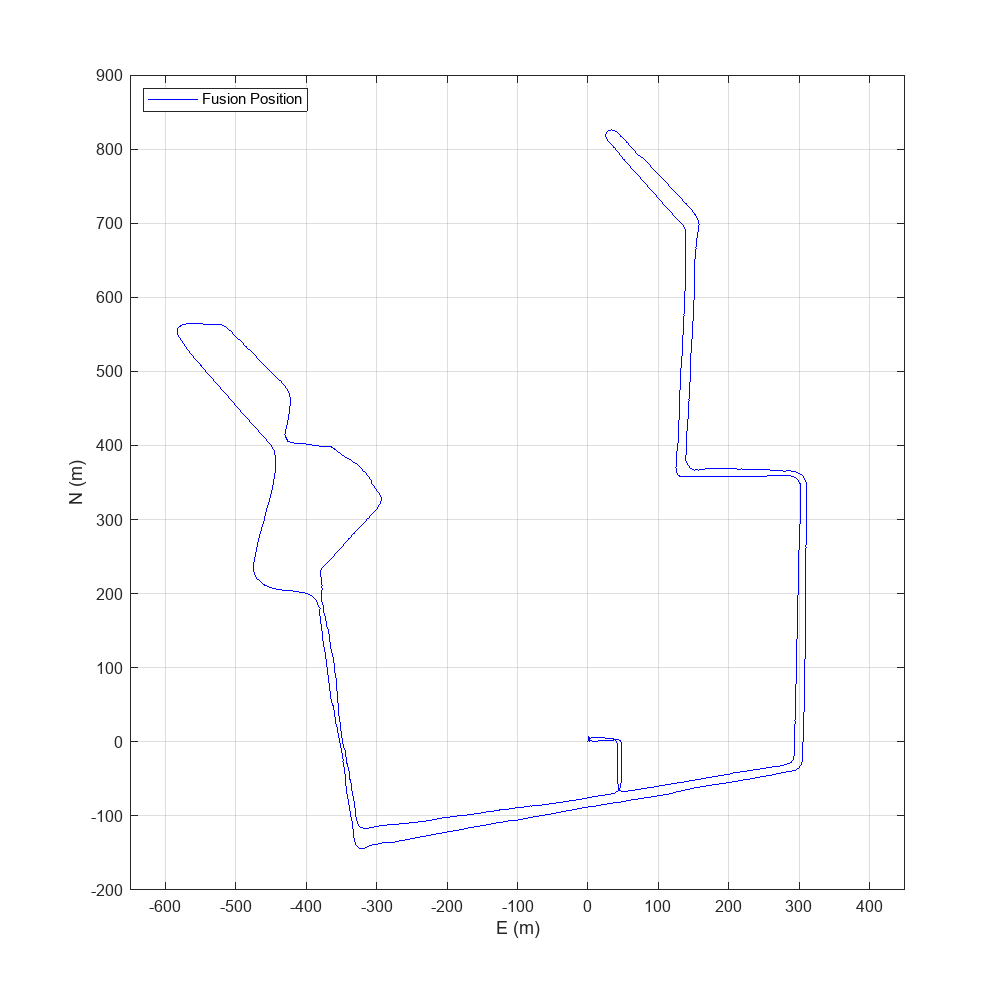

fig2 = figure;
set(fig2, 'Position', [100, 100, 800, 800]);
plot(p(:,2),p(:,1),'b', 'DisplayName','Fusion Position')
hold on;
% plot(referencePoints(:,2), referencePoints(:,1), 'r', 'DisplayName','Ref Position')
hold off;
grid on;
xlabel('E (m)');
ylabel('N (m)');
zlabel('D (m)');
legend('Location', 'Northwest');
axis([-650 450 -200 900 -50 50]);

#### Pengujian VIMU + GPS

% posErr = referencePoints - p;
% MSE_NED = mean(sqrt(posErr.^2))
% varposErrNED = var(posErr)